grid = gen_grid();
networks = metropolis_hasting(300);

burned = 0.0152

iterations = 0.0121

% Uncertainty plotter
% cell(1,n) = x_co
% cell(2,n) = y_co
% cell(3,n) = uncertainty
x_vec = cell(1,length(grid));
y_vec = cell(1,length(grid));
uncert_color = [];

% Classify all data points and assign unceratinty
for i = 1:length(grid)
    x = [grid(1,i); grid(2,i)];
    out = bayesian_classify(x, networks);
    x_vec{1,i} = grid(1,i);
    y_vec{1,i} = grid(2,i);
    uncert_color = [uncert_color; (abs(out(1)-out(2))) 0 0];
end

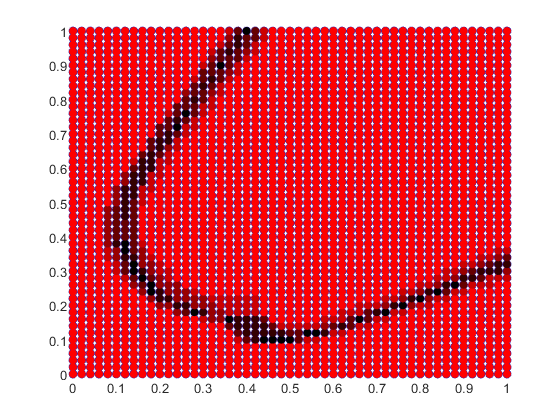


% Plot uncertaintys using a color gradient
hold on
axis([0 1 0 1])
x_vec = cell2mat(x_vec);
y_vec = cell2mat(y_vec);
scatter(x_vec,y_vec,[],uncert_color,'filled')